
clear;

csvFolderName = "StockVibro";
clockTimeLimit = 21; % 体験時間 (s)
stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

Stock Left

dt = 0.1;
T = 10;
xLimit = 100; % 単位 (mm)
clockTime = [
    (0:dt:T-dt)';
    (T:dt:2*T-dt)';
    ]

clockTime =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


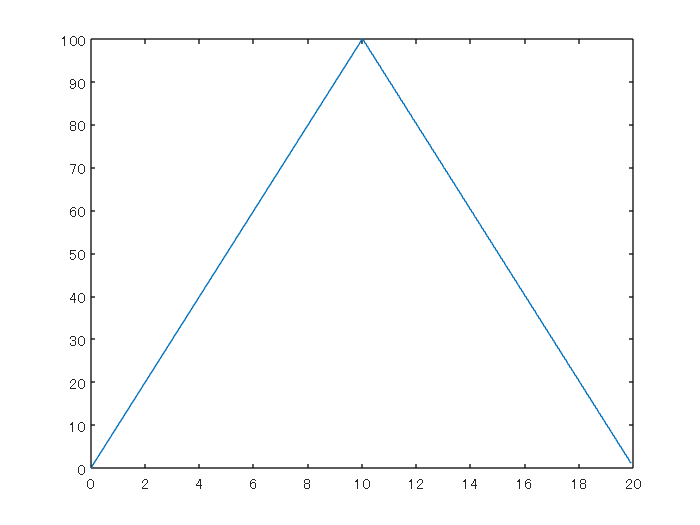


x = [
    xLimit * (0:dt:T-dt)'/T;
    -xLimit * ((T:dt:2*T-dt)' - T)/T + xLimit;
    ];
figure;
plot(clockTime, x);

StockVibroCSV = table(clockTime, x)

StockVibroCSV = 200×2 table
    clockTime    x 
    _________    __

         0        0
       0.1        1
       0.2        2
       0.3        3
       0.4        4
       0.5        5
       0.6        6
       0.7        7
       0.8        8
       0.9        9
         1       10
       1.1       11
       1.2       12
       1.3       13
       1.4       14
       1.5       15


writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end